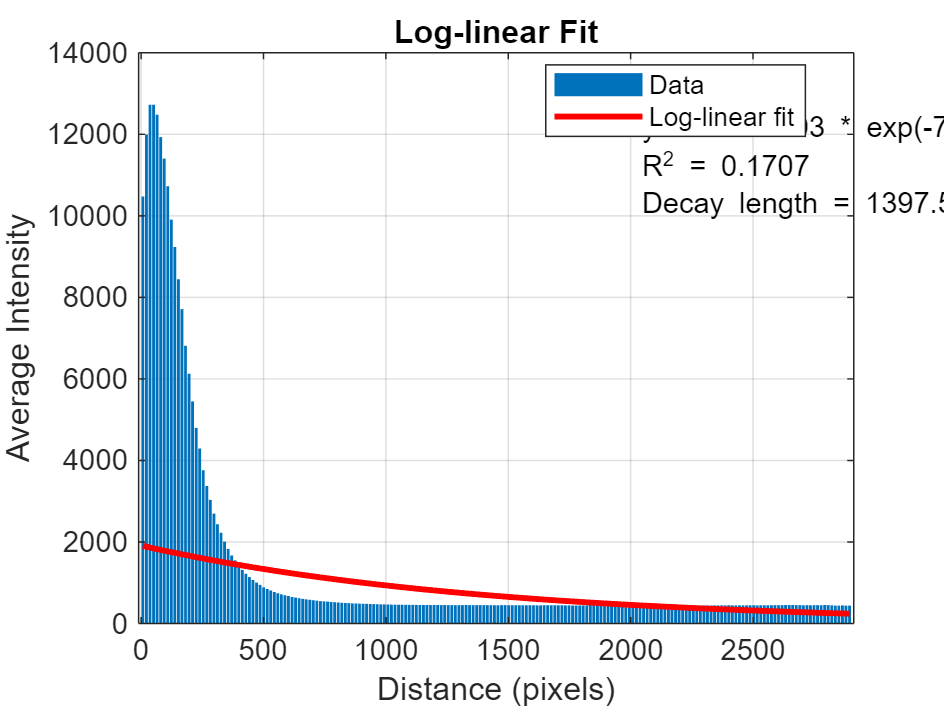

% guess what, it is the exact same code as wrapped.mlx
% Main script to process one image + plot to check fit
close all;
filename = "C:\Users\bear\Desktop\figure 1\sample 1_Merging_001.tif";
[intensity, params_log, params_lsq, counts, distances] = analyze_penetration_2(filename, 'raw');

% Extract parameters
a_log = params_log(1);
b_log = params_log(2);
decay_log = params_log(3);
R2_log = params_log(4);

a_lsq = params_lsq(1);
b_lsq = params_lsq(2);
decay_lsq = params_lsq(3);
R2_lsq = params_lsq(4);

% Generate fit curves using actual distances
y_fit_log = a_log * exp(b_log * distances);
y_fit_lsq = a_lsq * exp(b_lsq * distances);

% Plot Method 1 (Log-linear)
figure;
bar(distances, intensity, 'DisplayName', 'Data');
hold on;
plot(distances, y_fit_log, 'r-', 'LineWidth', 2, 'DisplayName', 'Log-linear fit');
xlabel('Distance (pixels)');
ylabel('Average Intensity');
title('Log-linear Fit');
legend('Location', 'best');
grid on;
text(0.7, 0.8, sprintf('y = %.2e * exp(%.2e * x)\nR^2 = %.4f\nDecay length = %.2f pixels', ...
    a_log, b_log, R2_log, decay_log), 'Units', 'normalized');

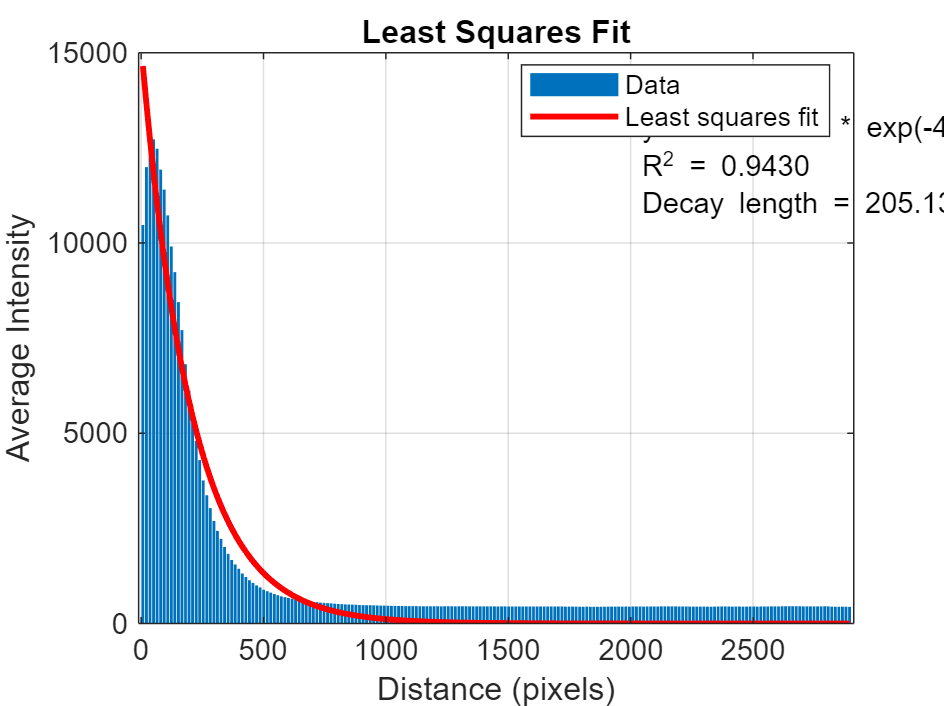


% Plot Method 2 (Least Squares)
figure;
bar(distances, intensity, 'DisplayName', 'Data');
hold on;
plot(distances, y_fit_lsq, 'r-', 'LineWidth', 2, 'DisplayName', 'Least squares fit');
xlabel('Distance (pixels)');
ylabel('Average Intensity');
title('Least Squares Fit');
legend('Location', 'best');
grid on;
text(0.7, 0.8, sprintf('y = %.2e * exp(%.2e * x)\nR^2 = %.4f\nDecay length = %.2f pixels', ...
    a_lsq, b_lsq, R2_lsq, decay_lsq), 'Units', 'normalized');


% Print results
fprintf('\nLog-linear fit results:\n');


Log-linear fit results:


fprintf('y = %.2e * exp(%.2e * x)\n', a_log, b_log);

y = 1.91e+03 * exp(-7.16e-04 * x)


fprintf('R-squared: %.4f\n', R2_log);

R-squared: 0.1707


fprintf('Decay length: %.2f pixels\n', decay_log);

Decay length: 1397.54 pixels



fprintf('\nLeast squares fit results:\n');


Least squares fit results:


fprintf('y = %.2e * exp(%.2e * x)\n', a_lsq, b_lsq);

y = 1.52e+04 * exp(-4.87e-03 * x)


fprintf('R-squared: %.4f\n', R2_lsq);

R-squared: 0.9430


fprintf('Decay length: %.2f pixels\n', decay_lsq);

Decay length: 205.13 pixels


% Main script for batch processing
folder_path = "C:\Users\bear\Desktop\figure 1";
files = dir(fullfile(folder_path, '*_Merging_001.tif'));
background_methods = ["raw", "five", "ten"];

for m = 1:length(background_methods)
    current_method = background_methods(m);
    
    % Initialize arrays to store results
    num_files = length(files);
    results = table('Size', [num_files 9], ...
        'VariableTypes', {'string', 'double', 'double', 'double', 'double', 'double', 'double', 'double', 'double'}, ...
        'VariableNames', {'Filename', ...
        'Log_Amplitude', 'Log_DecayRate', 'Log_DecayLength', 'Log_Rsquared', ...
        'LSQ_Amplitude', 'LSQ_DecayRate', 'LSQ_DecayLength', 'LSQ_Rsquared'});
    
    % Process each file
    for i = 1:num_files
        current_file = fullfile(folder_path, files(i).name);
        [intensity, params_log, params_lsq, ~, ~] = analyze_penetration_2(current_file, current_method);
        
        % Store results in table
        results.Filename(i) = files(i).name;
        results.Log_Amplitude(i) = params_log(1);
        results.Log_DecayRate(i) = params_log(2);
        results.Log_DecayLength(i) = params_log(3);
        results.Log_Rsquared(i) = params_log(4);
        results.LSQ_Amplitude(i) = params_lsq(1);
        results.LSQ_DecayRate(i) = params_lsq(2);
        results.LSQ_DecayLength(i) = params_lsq(3);
        results.LSQ_Rsquared(i) = params_lsq(4);
    end
    output_filename = sprintf('penetration_analysis_%s.xlsx', current_method);
    writetable(results, fullfile(folder_path, output_filename));
end

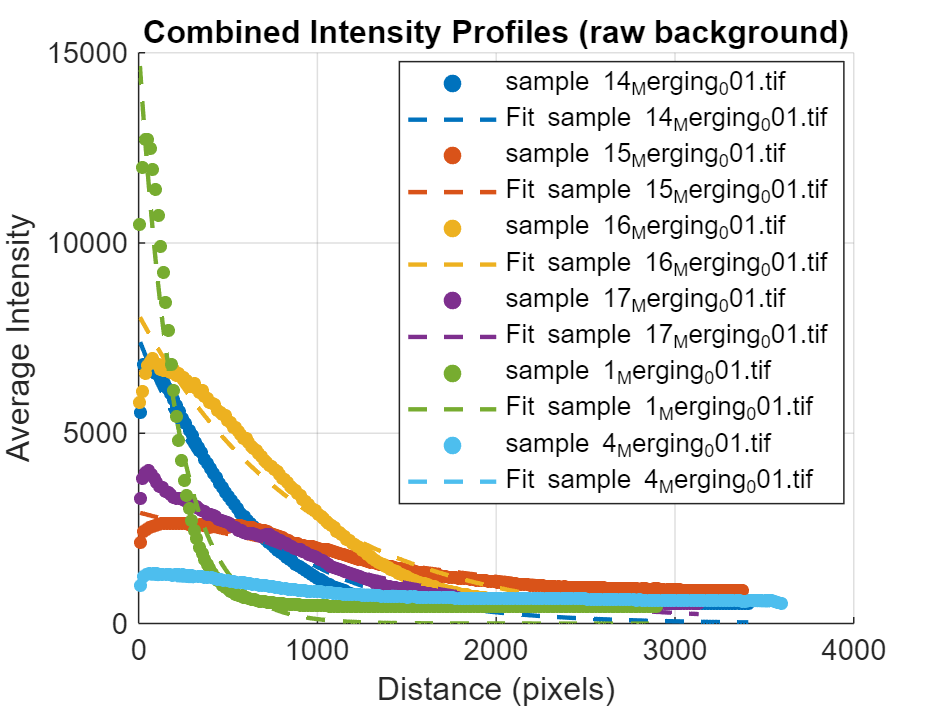

% Main script for graph generation
folder_path = "C:\Users\bear\Desktop\figure 1\graph";
files = dir(fullfile(folder_path, '*_Merging_001.tif'));
background_methods = ["raw", "five", "ten"];
background_methods = ["raw"];

for m = 1:length(background_methods)
    current_method = background_methods(m);
    
    % Initialize arrays to store results
    num_files = length(files);
    
    % Create cell arrays to store intensity profiles and distances for each file
    all_intensities = cell(num_files, 1);
    all_distances = cell(num_files, 1);
    all_fits = cell(num_files, 1);
    
    % Store parameters in arrays
    all_amplitudes = zeros(num_files, 1);
    all_decay_rates = zeros(num_files, 1);
    all_decay_lengths = zeros(num_files, 1);
    all_r_squared = zeros(num_files, 1);
    
    % Process each file
    for i = 1:num_files
        current_file = fullfile(folder_path, files(i).name);
        [intensity, params_log, params_lsq, ~, distances] = analyze_penetration_2(current_file, current_method);
        
        % Store the intensity profile and distances
        all_intensities{i} = intensity;
        all_distances{i} = distances;
        
        % Store LSQ parameters
        all_amplitudes(i) = params_lsq(1);
        all_decay_rates(i) = params_lsq(2);
        all_decay_lengths(i) = params_lsq(3);
        all_r_squared(i) = params_lsq(4);
        
        % Calculate and store the fit
        all_fits{i} = params_lsq(1) * exp(params_lsq(2) * distances);
    end
    
    % Plot combined graph
    figure('Position', [100, 100, 800, 600]);
    hold on;
    
    % Plot each sample's data and fit
    colors = lines(num_files); % Get different colors for each sample
    for i = 1:num_files
        % Plot data points
        scatter(all_distances{i}, all_intensities{i}, 20, colors(i,:), 'filled', 'DisplayName', files(i).name);
        % Plot fit
        plot(all_distances{i}, all_fits{i}, '--', 'Color', colors(i,:), 'LineWidth', 1.5, 'DisplayName', sprintf('Fit %s', files(i).name));
    end
    
    xlabel('Distance (pixels)');
    ylabel('Average Intensity');
    title(sprintf('Combined Intensity Profiles (%s background)', current_method));
    legend('Location', 'best');
    grid on;
    
    % Add text box with average parameters
    mean_decay_length = mean(all_decay_lengths);
    std_decay_length = std(all_decay_lengths);
    
    % Save the figure
    saveas(gcf, fullfile(folder_path, sprintf('combined_profiles_%s.png', current_method)));
end

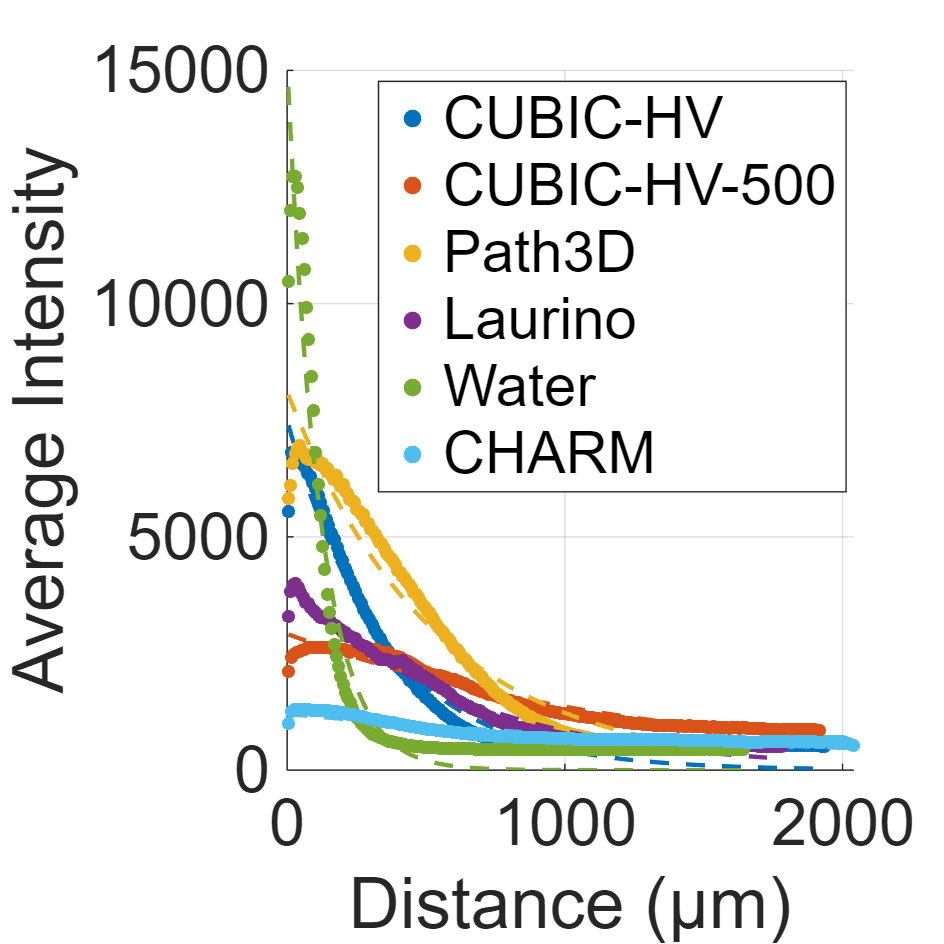

% new graph (please run the above code first)
figure('Position', [100, 100, 600, 600]);
hold on;
staining_methods = {'CUBIC-HV', 'CUBIC-HV-500', 'Path3D', 'Laurino', 'Water', 'CHARM'};

% Set font size
fontsize = 22;
set(gca, 'FontSize', fontsize);

% Plot each sample's data and fit
colors = lines(num_files); % Get different colors for each sample
for i = 1:num_files
    % Plot data points
    scatter(all_distances{i} * 0.5677, all_intensities{i}, 20, colors(i,:), 'filled', 'DisplayName', staining_methods{i});
    % Plot fit
    plot(all_distances{i} * 0.5677, all_fits{i}, '--', 'Color', colors(i,:), 'LineWidth', 1.5, 'HandleVisibility', 'off');
end

xlabel('Distance (µm)');
ylabel('Average Intensity');
% title('Staining intensity decay from tissue surface');
legend('Location', 'best');
grid on;

% Add text box with average parameters
mean_decay_length = mean(all_decay_lengths);
std_decay_length = std(all_decay_lengths);

% Save the figure
saveas(gcf, fullfile(folder_path, sprintf('combined_profiles_%s.png', current_method)));